# Lab 7– Convolution-II ∗ 

# EE252L: Signals and Systems Lab 

# Dr. Basit Memon and Ms. Hira Mustafa

## Name: M. Shees Abbas                          ID: ma11212

## Task 1

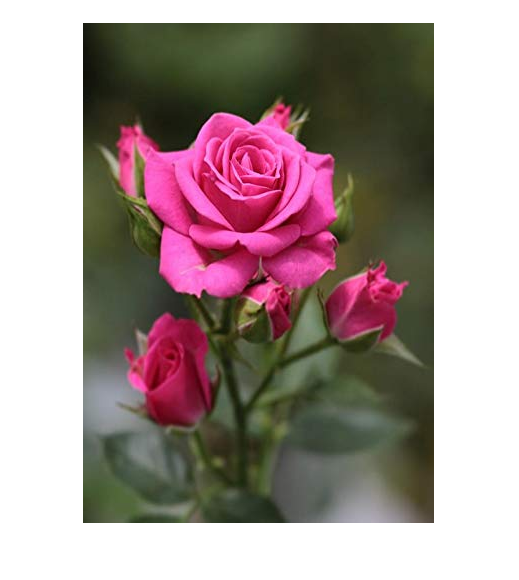

%Read image, visualize it, and display its size and class.
I = imread("flower.jpg");
% Convert to double precision
I = im2double(I);
% Display
figure,
imshow(I)

whos I

  Name        Size                 Bytes  Class     Attributes

  I         500x351x3            4212000  double              




% Split the image into the 3 component color intensity planes or matrices.
[R, G, B] = imsplit(I);
whos R

  Name        Size               Bytes  Class     Attributes

  R         500x351            1404000  double              




% Create a 2-D convolution filter or kernel for averaging or smoothing
W = 5;
h = ones(W)./W.^2;

%Convolve R with h to blur the image
Ravg = conv2(R,h,"same");
% Convolve G with h to blur the image
Gavg = conv2(G,h,"same"); 
% Convolve B with h to blur the image
Bavg = conv2(B,h,"same");
% Concatenate the three matrices to put together the color image
Iavg = cat(3,Ravg,Gavg,Bavg);
whos Iavg

  Name        Size                 Bytes  Class     Attributes

  Iavg      500x351x3            4212000  double              



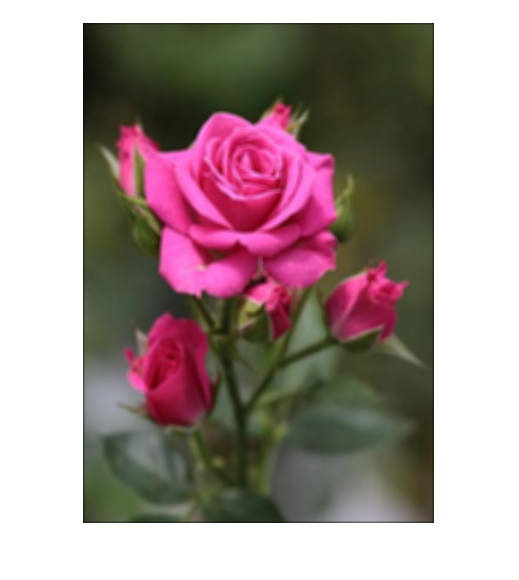

imshow(Iavg,[])



%Read image, visualize it, and display its size and class.
I = imread("flower.jpg");
% Convert to double precision
I = im2double(I);
% Display
figure,
imshow(I)

whos I

  Name        Size                 Bytes  Class     Attributes

  I         500x351x3            4212000  double              




% Split the image into the 3 component color intensity planes or matrices.
[R, G, B] = imsplit(I);
whos R

  Name        Size               Bytes  Class     Attributes

  R         500x351            1404000  double              




% Create a 2-D convolution filter or kernel for averaging or smoothing
W = 10;
h = ones(W)./W.^2;

%Convolve R with h to blur the image
Ravg = conv2(R,h,"same");
% Convolve G with h to blur the image
Gavg = conv2(G,h,"same"); 
% Convolve B with h to blur the image
Bavg = conv2(B,h,"same");
% Concatenate the three matrices to put together the color image
Iavg = cat(3,Ravg,Gavg,Bavg);
whos Iavg

  Name        Size                 Bytes  Class     Attributes

  Iavg      500x351x3            4212000  double              



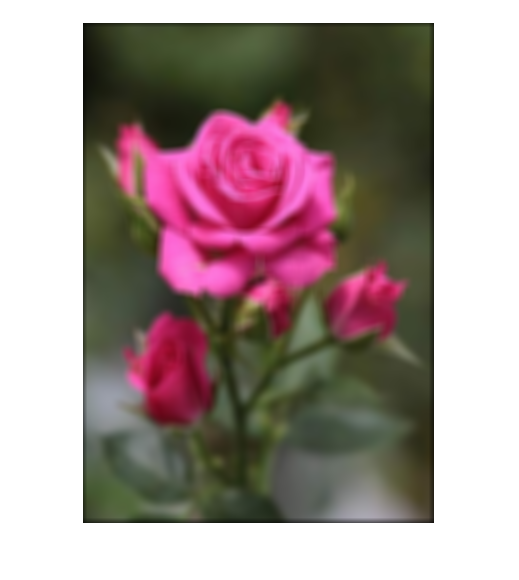

imshow(Iavg,[])

 1) Increase the filter size W. What is the effect of increasing the size of the filter?

Each output pixel is the average of a W×W neighborhood. A larger W means each pixel averages over more neighbors, so the image gets blurrier

2) Look closely at the boundaries of the output image. What happens to the border pixels? Why?

With `conv2`, the output is the same size as the input, but near the edges the kernel window hangs off the image. MATLAB assumes the pixels outside the image are zero. So at a border pixel, part of the window includes imaginary black (0) pixels, and the average gets pulled toward zero.

## Task 2

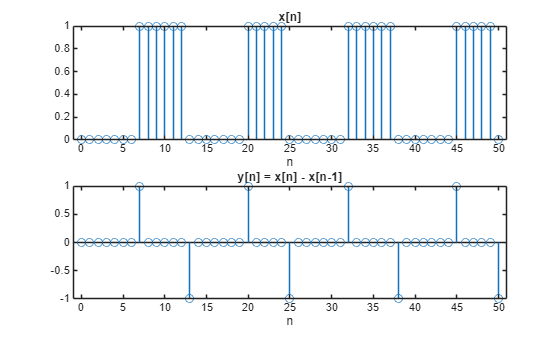

n = 0:50;
x = double((sin(0.5*n) + 0.2) < 0);   

h = [1 -1];                            
y = conv(x, h);                        
y = y(1:length(x));                    

figure
subplot(2,1,1)
stem(n, x) 
title('x[n]') 
xlabel('n')
subplot(2,1,2)
stem(n, y)
title('y[n] = x[n] - x[n-1]')
xlabel('n')

## Task 3

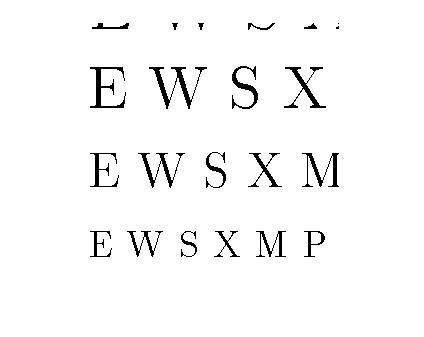

load echart.mat;
figure;
imshow(echart)

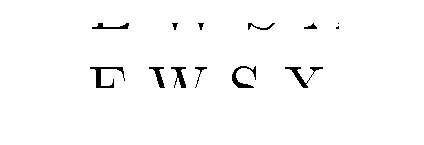

figure;
imshow(echart(1:65,:))

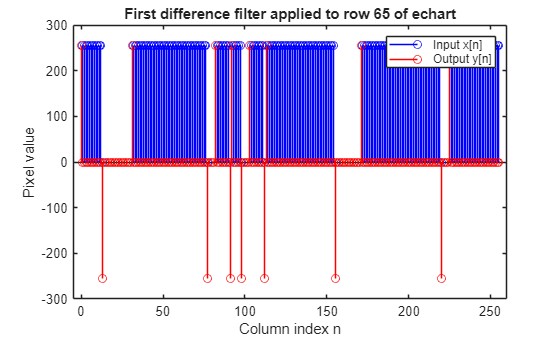


row = double(echart(65,:));
n = 0:length(row)-1;

h = [1 -1];
y = conv(row, h);
y = y(1:length(row));

figure
stem(n, row, 'b')
hold on
stem(n, y, 'r')
hold off
title('First difference filter applied to row 65 of echart')
xlabel('Column index n')
ylabel('Pixel value')
legend('Input x[n]', 'Output y[n]')

In the input signal, 0 represents a black pixel (part of a letter stroke) and 255 represents a white pixel (the background), so the row is mostly white with short black runs wherever the scan line crosses a letter. In the output signal y[n] = x[n] − x[n−1], a value of 0 means neighboring pixels are the same, so the scan is inside a flat region that is all white or all black. A value of −255 means the pixel went from white to black, which marks the left edge of a letter stroke, and +255 means it went from black to white, which marks the right edge. So the non-zero outputs mark the edges, and the sign shows the direction of the change.

## Task 4

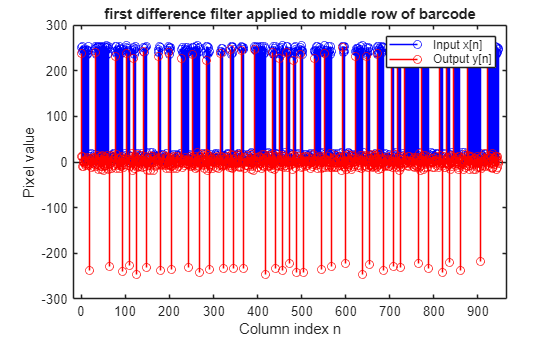

clc;
clear close all;
I = imread("HP110v3.png");
[row, cols] = size(I);
mid = round(row/2);
x = double(I(mid, :));
h = [1 -1];
y = conv(x,h);
y = y(1:length(x));
n = 0:length(x)-1;

figure
stem(n, x, 'b')
hold on
stem(n, y, 'r')
hold off
title('first difference filter applied to middle row of barcode')
xlabel('Column index n')
ylabel('Pixel value')
legend('Input x[n]', 'Output y[n]')

The spike magnitudes differ because the pixel values in the image are not perfectly 0 and 255. Due to noise s, the white pixels range from about 235 to 255 and the black pixels from about 0 to 20. Each spike in y[n] is the difference between two neighboring pixels at an edge, so its size depends on exactly which values meet there. A bright white (255) next to a dark black (0) gives a spike near 255, while a duller white (235) next to a grayer black (20) gives only about 215. 

tau = 200;
d = abs(y) >= tau;

The `find` function returns the indices (positions) of all non-zero elements in an array, not the values themselves. For a logical or 0/1 vector like d, it returns the positions where d is 1 (true). from which we will create our position signal l when will point to the every transition point between white and black region of barcode

l = find(d);
delta = conv(l, h);
delta = delta(2:length(l));
section = delta(6:64);

theta = sum(section)/95;

bar_widths = round(section/theta);

decodeUPC(bar_widths)

ssbeg =      1     1     1


ans =      8     8     2     7     8     0     4     5     0     1     6     5
